## Data Setup and Cleaning

% Load the data as a MATLAB table
path = "la-haute-borne-data-2017-2020.csv"

path = "la-haute-borne-data-2017-2020.csv"

d = readtable(path)

d = 52560×138 table
    Wind_turbine_name              Date_time              Ba_avg    Ba_min    Ba_max    Ba_std    Rt_avg    Rt_min    Rt_max    Rt_std    DCs_avg    DCs_min    DCs_max    DCs_std    Cm_avg    Cm_min    Cm_max    Cm_std    P_avg     P_min     P_max     P_std     Q_avg    Q_min     Q_max     Q_std    S_avg     S_min     S_max     S_std     Cosphi_avg    Cosphi_min    Cosphi_max    Cosphi_std    

% Setup Variables
variables = ["Ba_avg", "Ws_avg", "Ds_avg", "Rm_avg", "Ot_avg"]

variables = 1×5 string array
    "Ba_avg"    "Ws_avg"    "Ds_avg"    "Rm_avg"    "Ot_avg"


variables_named = ["Pitch Angle", "Wind Speed", "Generator Speed", "Torque", "Outdoor Temperature"]

variables_named = 1×5 string array
    "Pitch Angle"    "Wind Speed"    "Generator Speed"    "Torque"    "Outdoor Temperature"


additional_data = ["Wind_turbine_name", "Date_time", "P_avg"]

additional_data = 1×3 string array
    "Wind_turbine_name"    "Date_time"    "P_avg"



data = d(:, [variables, additional_data])

data = 52560×8 table
    Ba_avg    Ws_avg    Ds_avg    Rm_avg    Ot_avg    Wind_turbine_name              Date_time              P_avg 
    ______    ______    ______    ______    ______    _________________    _____________________________    ______

     9.77       4.8     908.13    656.51    20.81        {'R80790'}        {'2017-10-18 10:30:00+01:00'}     94.71
        0      3.92     972.84    151.25    21.74        {'R80790'}        {'2017-10-18 11:10:00+01:00'}     15.59
    -0.17      3.89     970.59    204.88    21.46        {'R80790'}        {'2017-10-18 12:40:00+01:00'}     20.87
       -1      5.79     1423.4    2177.3    17.82        {'R80790'}        {'2017-10-18 22:50:00+01:00'}    328.78
       -1      5

data = renamevars(data, variables, variables_named)

data = 52560×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name              Date_time              P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    _____________________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        {'2017-10-18 10:30:00+01:00'}     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        {'2017-10-18 11:10:00+01:00'}     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        {'2017-10-18 12:


% Remove any data points which are not the same wind turbine
data = data(data.Wind_turbine_name == "R80790", :)

data = 52560×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name              Date_time              P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    _____________________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        {'2017-10-18 10:30:00+01:00'}     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        {'2017-10-18 11:10:00+01:00'}     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        {'2017-10-18 12:


% Remove any rows which contain missing values
data = rmmissing(data)

data = 51608×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name              Date_time              P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    _____________________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        {'2017-10-18 10:30:00+01:00'}     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        {'2017-10-18 11:10:00+01:00'}     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        {'2017-10-18 12:


% Convert date column to datetime objects
data.Date_time = datetime(data.Date_time,"InputFormat", "yyyy-MM-dd HH:mm:SSz", "TimeZone", "UTC")

data = 51608×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name         Date_time          P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    ____________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        18-Oct-2017 09:30:00     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        18-Oct-2017 10:10:00     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        18-Oct-2017 11:40:00     20.87
          -1         

k = length(variables_named)

k = 5

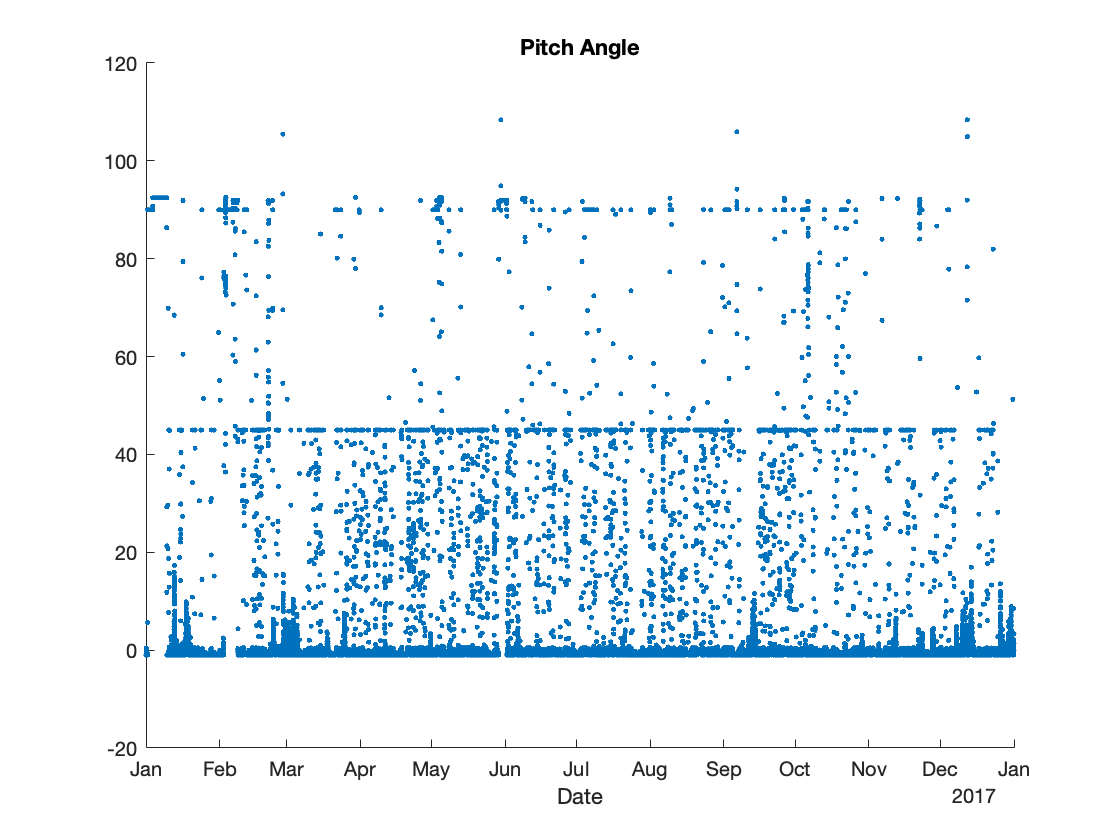

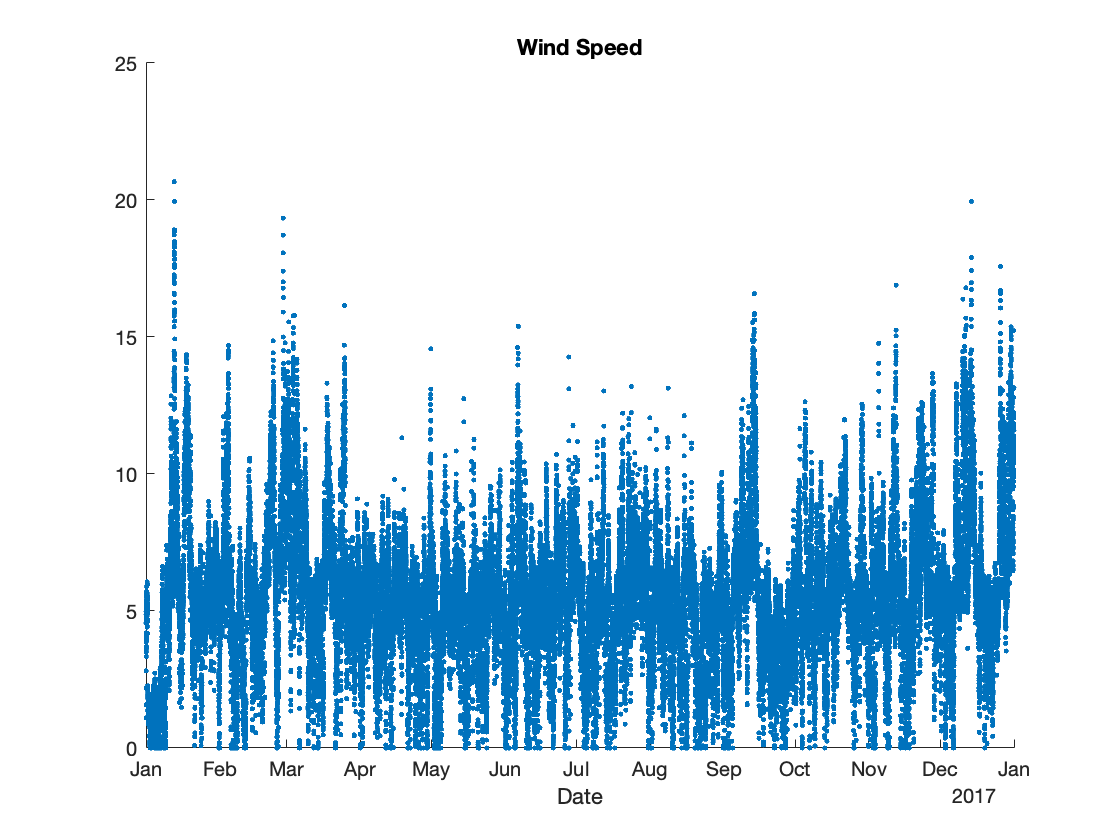

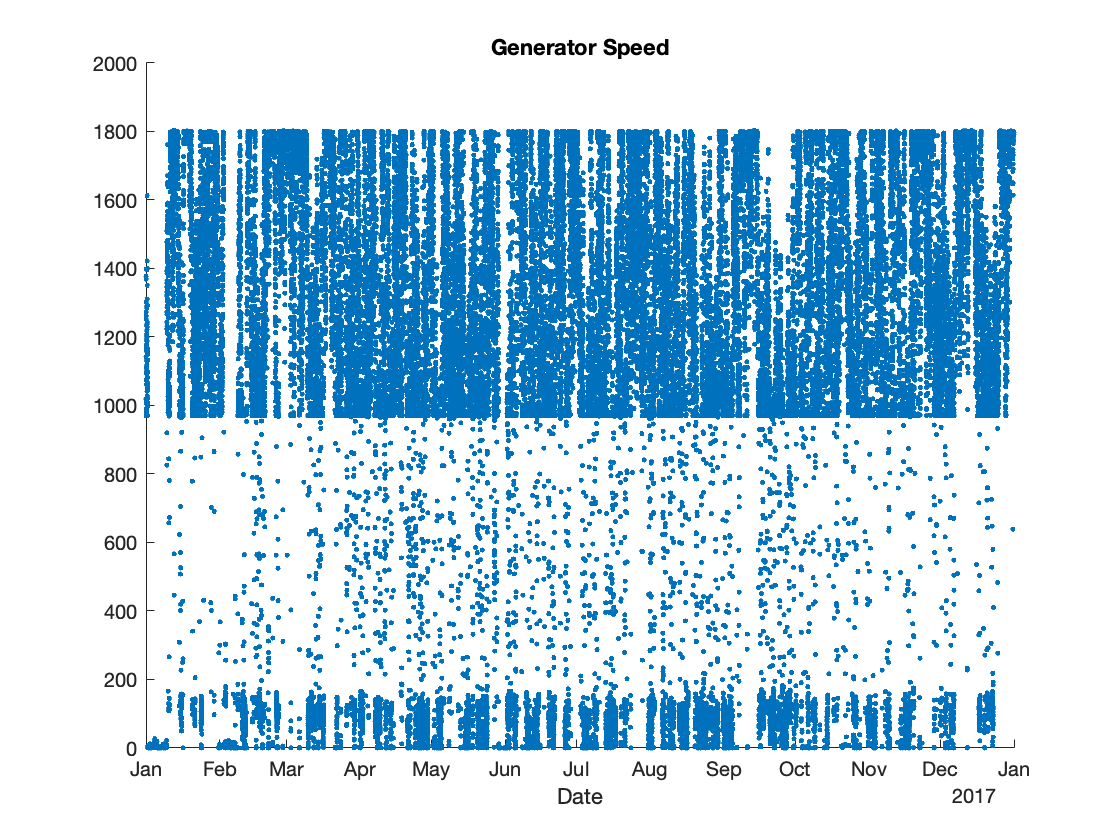

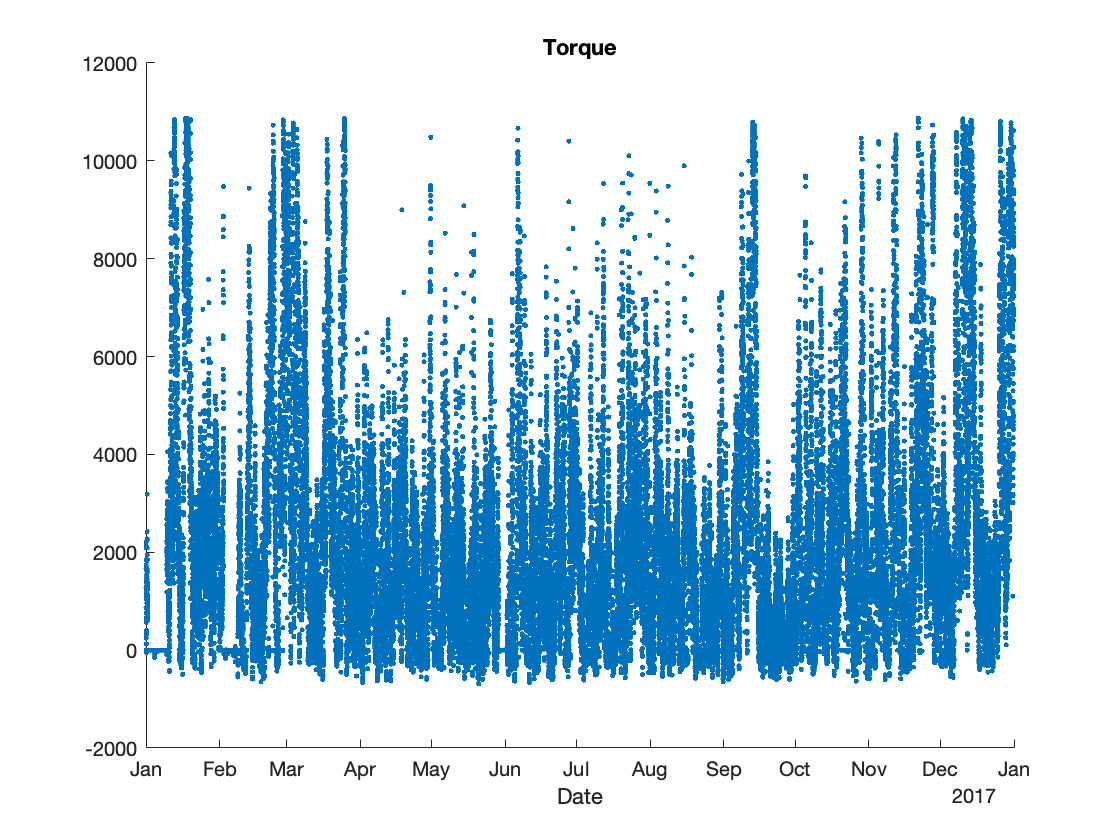

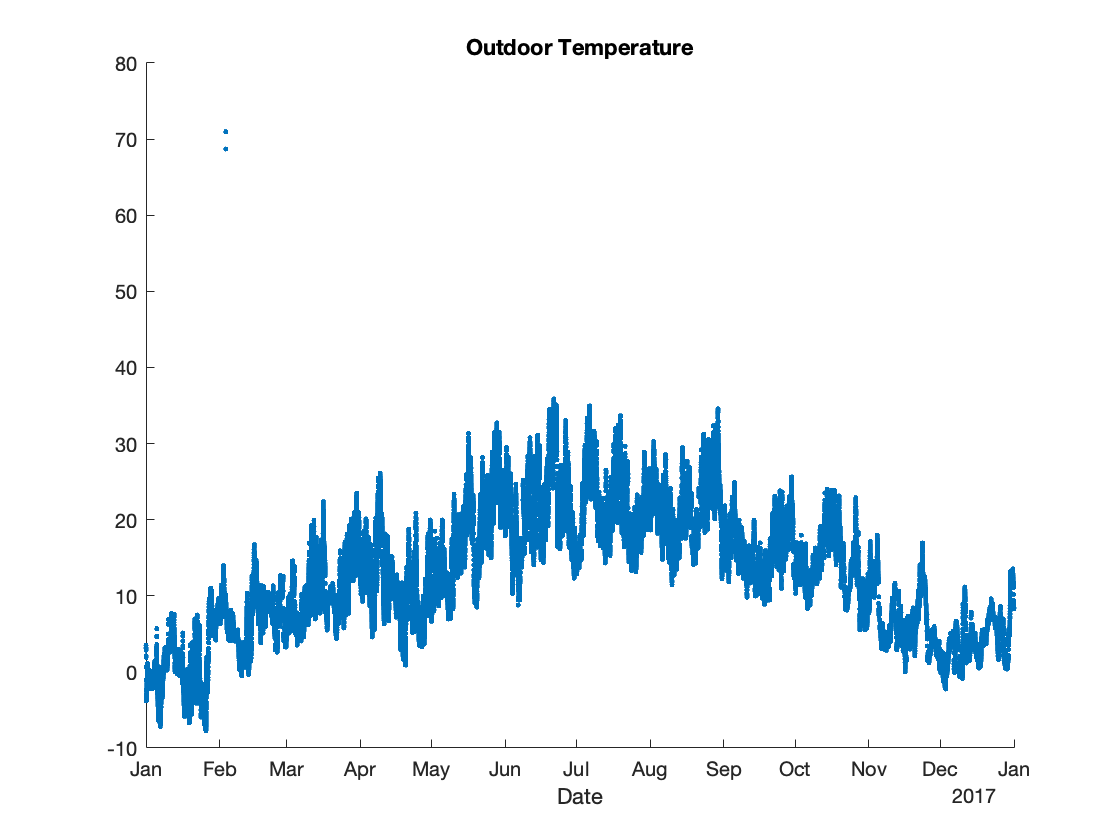


% Plot against time data to get an idea of common values and outliers
for i = 1:k
    figure(i)
    scatter(data.Date_time, data.(variables_named(i)), ".")
    title(variables_named(i))
    xlabel("Date")
end

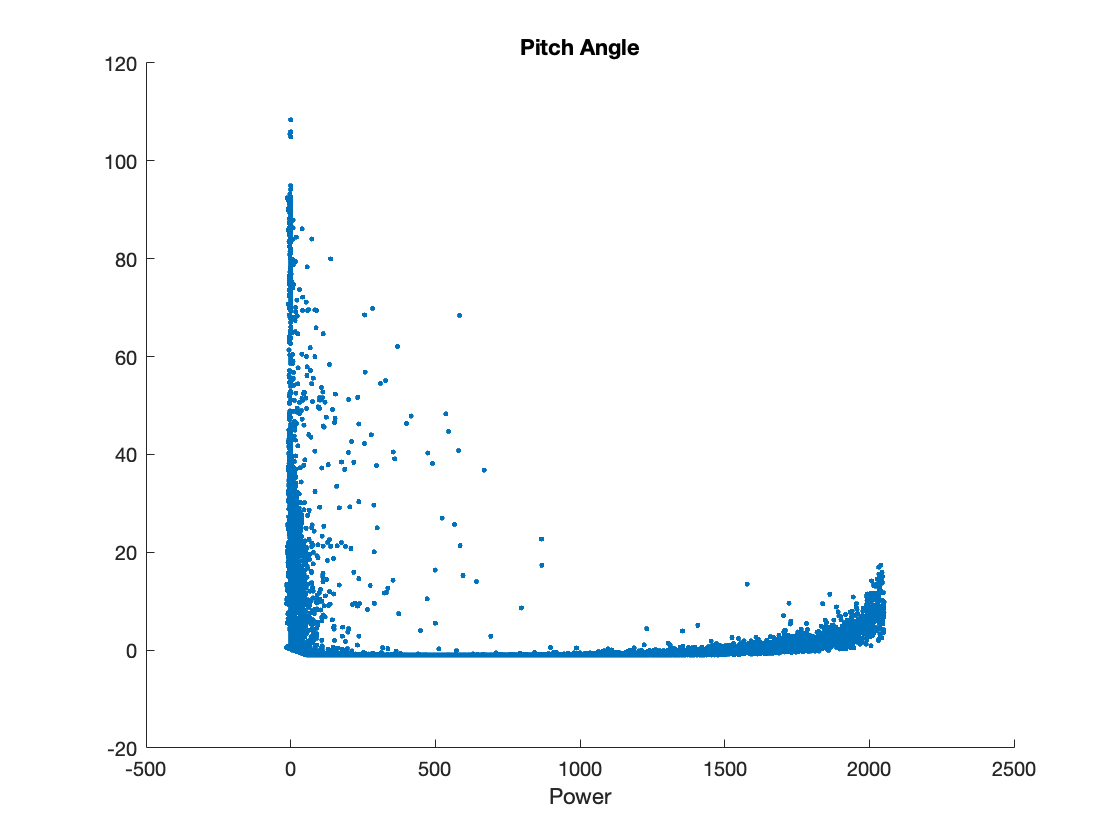

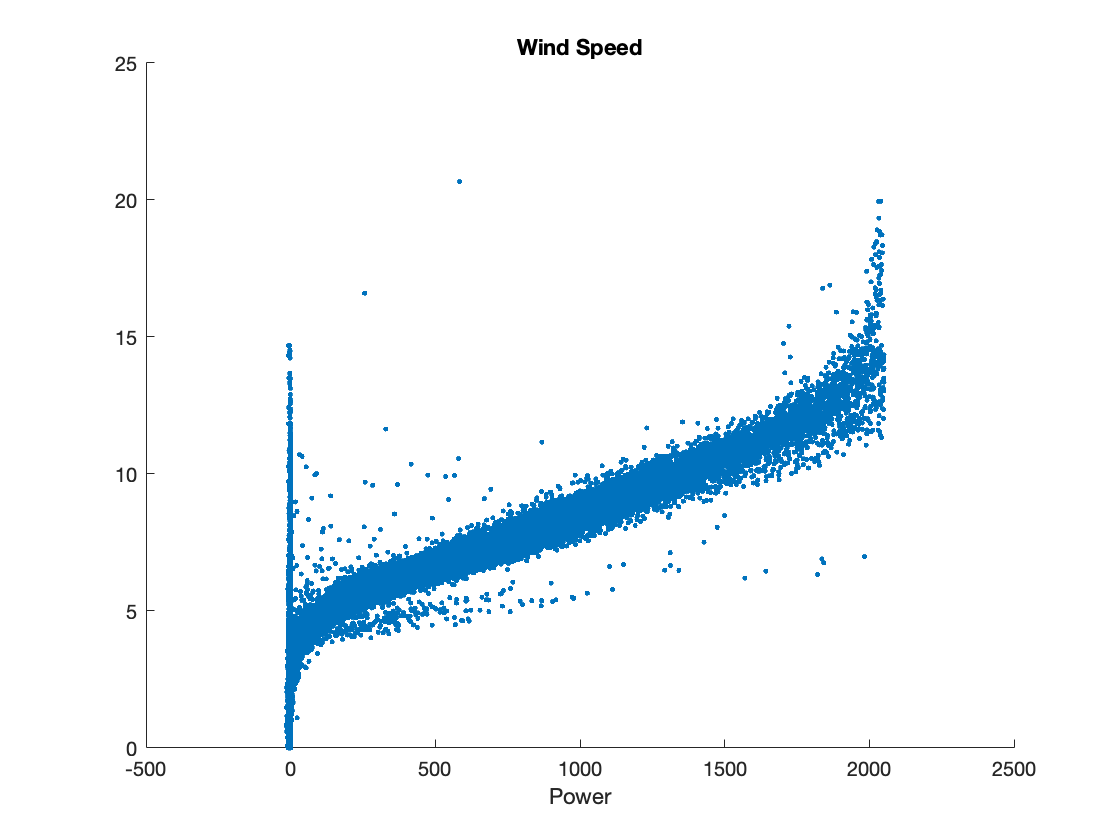

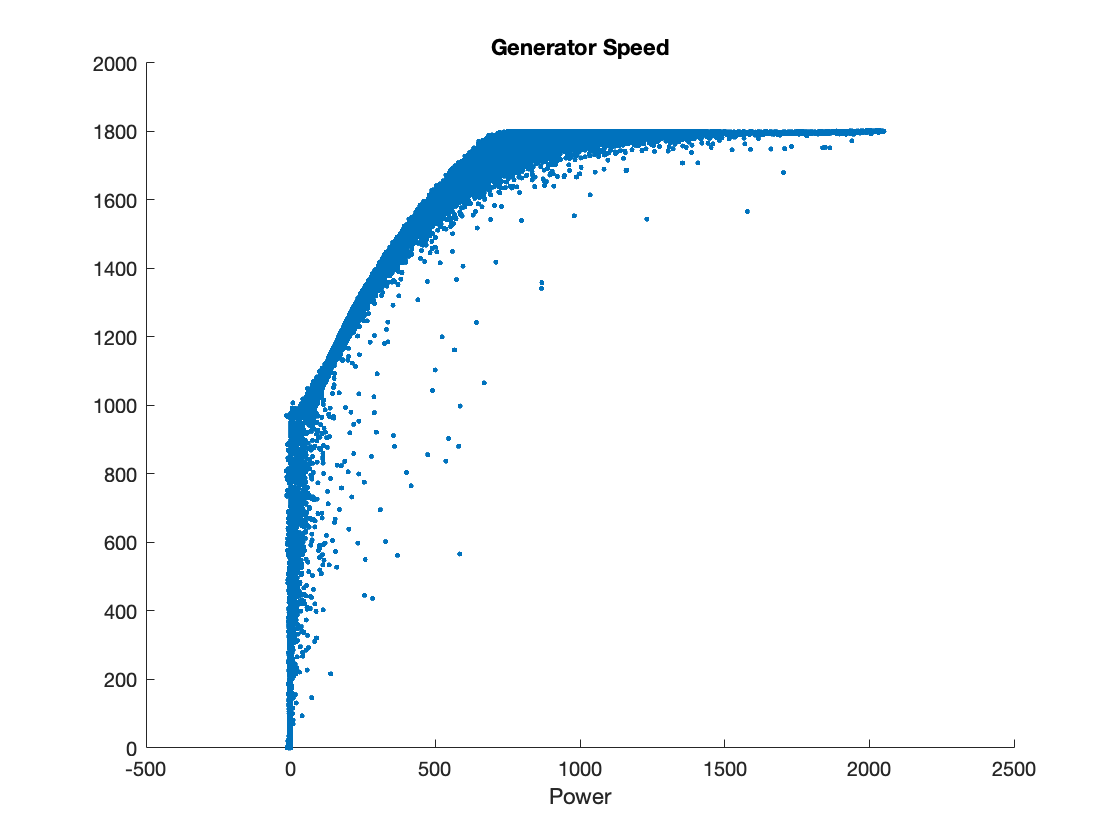

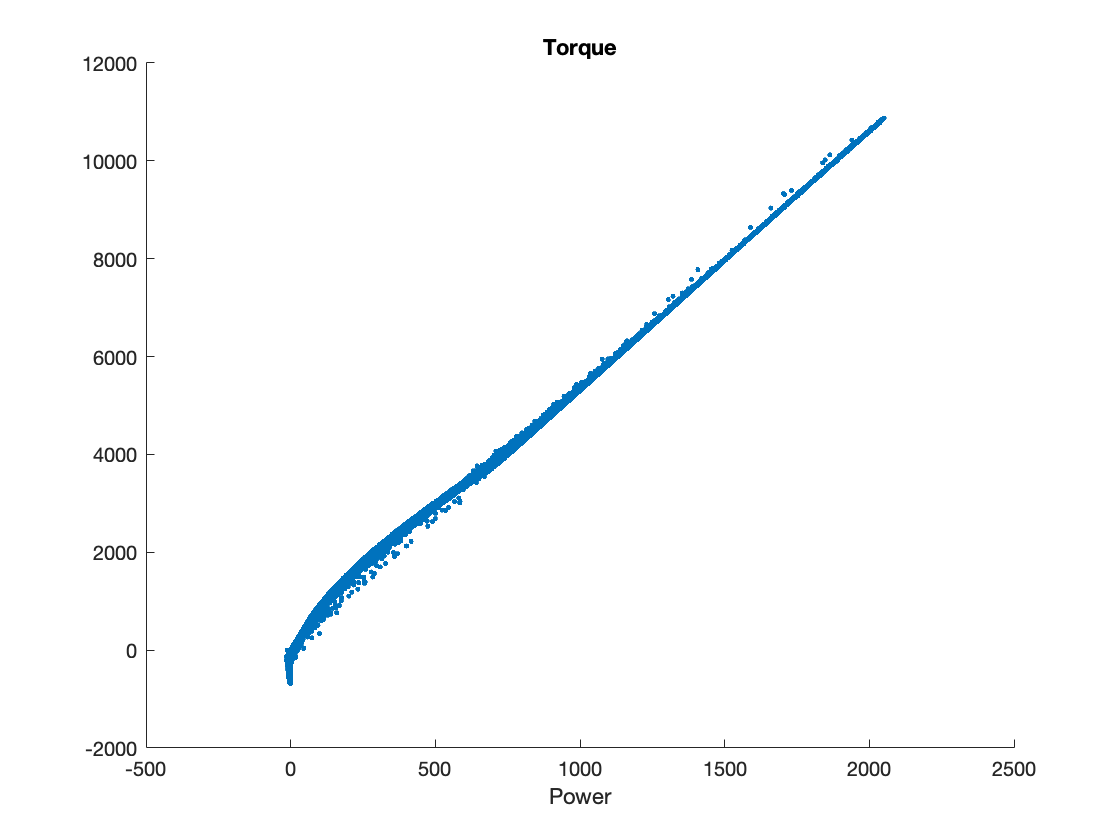

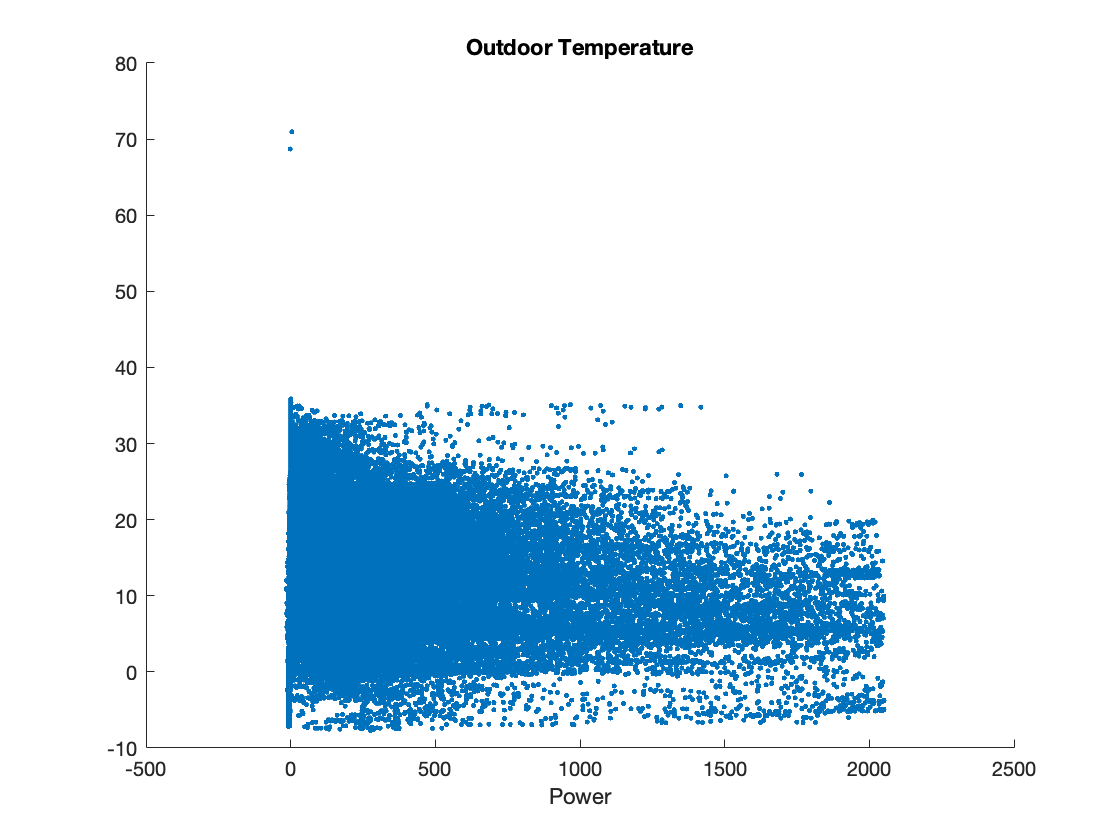

% Plot against power to get an idea of trends
for i = 1:k
    figure(i)
    scatter(data.P_avg, data.(variables_named(i)), ".")
    title(variables_named(i))
    xlabel("Power")
end

% Remove data with pitch angles greater than 90
data = data(data.("Pitch Angle") < 90, :)

data = 49968×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name         Date_time          P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    ____________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        18-Oct-2017 09:30:00     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        18-Oct-2017 10:10:00     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        18-Oct-2017 11:40:00     20.87
          -1         

% Remove data with with low power and not low wind speeds
data = data(~(data.("Wind Speed") > 5 & data.("P_avg") < 50), :)

data = 49353×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name         Date_time          P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    ____________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        18-Oct-2017 09:30:00     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        18-Oct-2017 10:10:00     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        18-Oct-2017 11:40:00     20.87
          -1         

% Remove data with temperature higher than 50
data = data(data.("Outdoor Temperature") < 50, :)

data = 49353×8 table
    Pitch Angle    Wind Speed    Generator Speed    Torque    Outdoor Temperature    Wind_turbine_name         Date_time          P_avg 
    ___________    __________    _______________    ______    ___________________    _________________    ____________________    ______

        9.77           4.8           908.13         656.51           20.81              {'R80790'}        18-Oct-2017 09:30:00     94.71
           0          3.92           972.84         151.25           21.74              {'R80790'}        18-Oct-2017 10:10:00     15.59
       -0.17          3.89           970.59         204.88           21.46              {'R80790'}        18-Oct-2017 11:40:00     20.87
          -1         

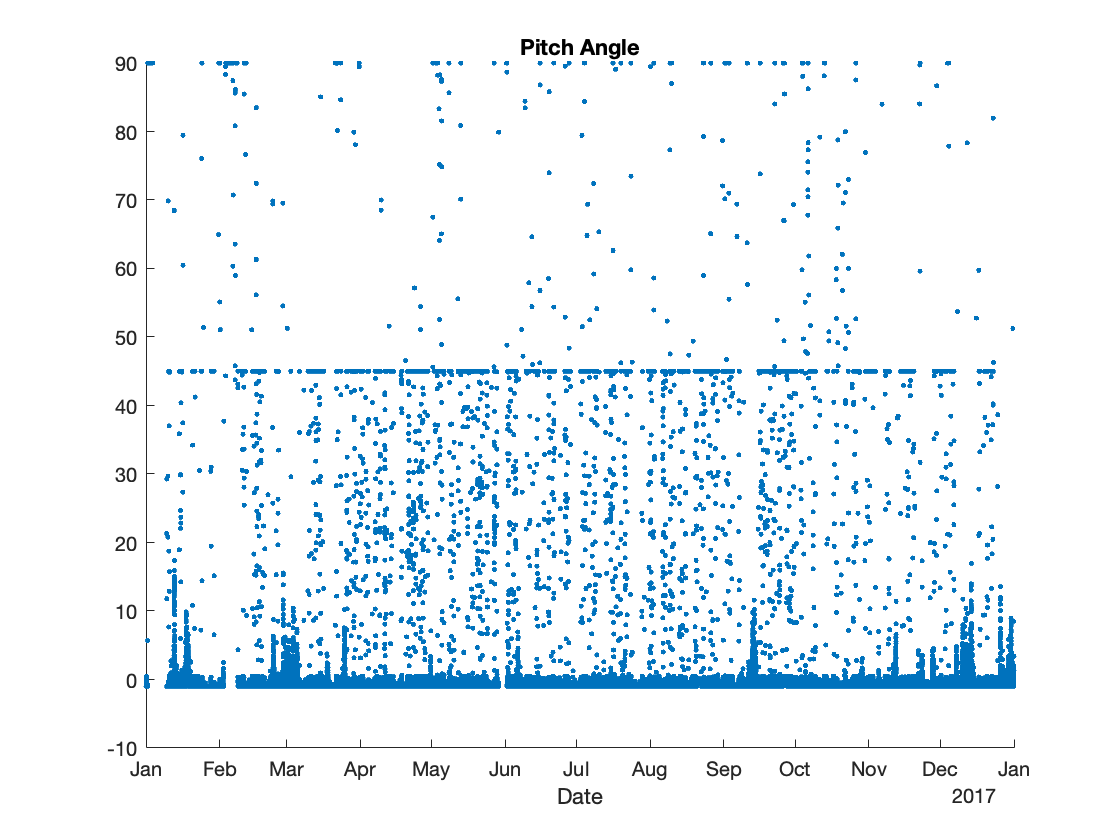

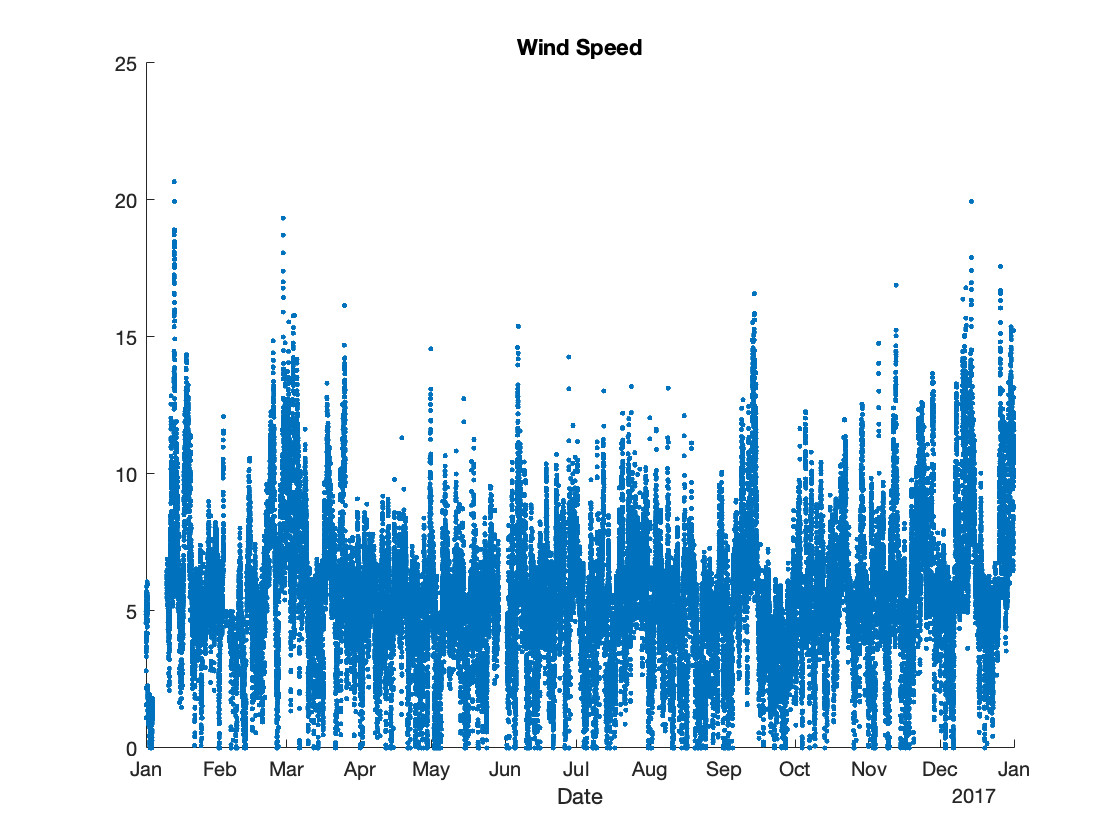

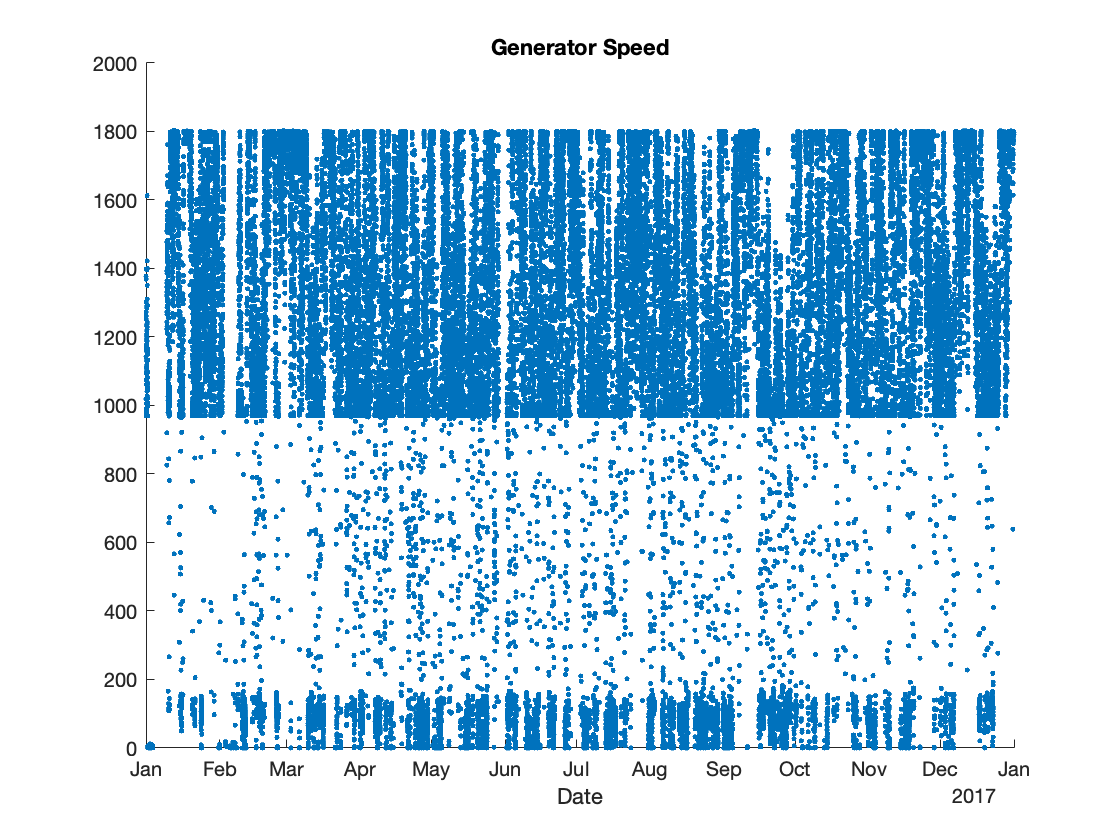

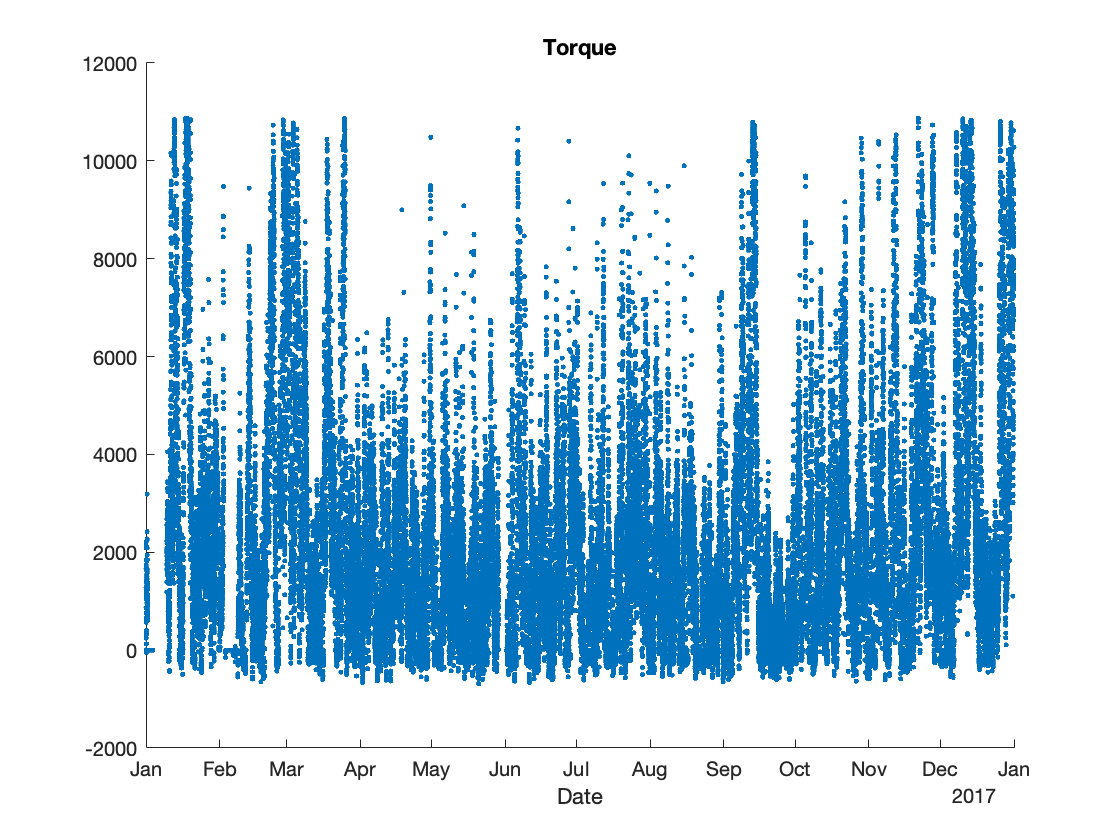

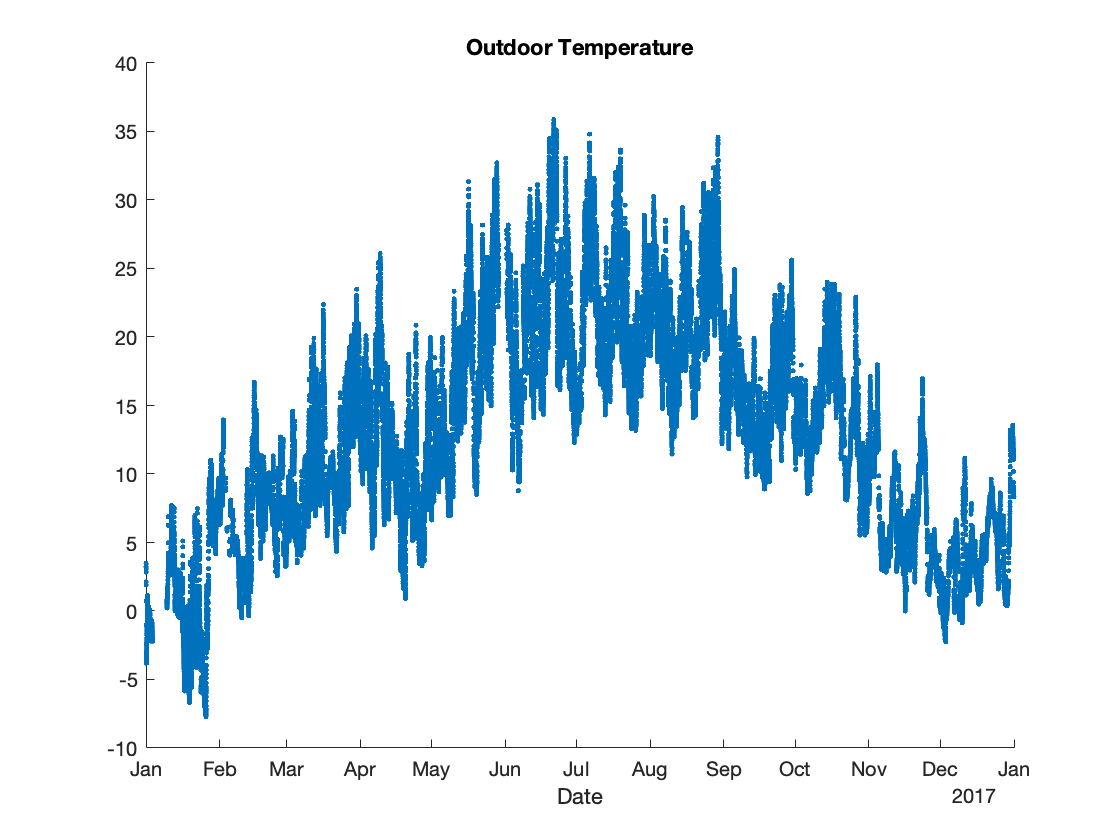

% Plot the data again for visual confirmation of outlier removal
for i = 1:k
    figure(i)
    scatter(data.Date_time, data.(variables_named(i)), ".")
    title(variables_named(i))
    xlabel("Date")
end

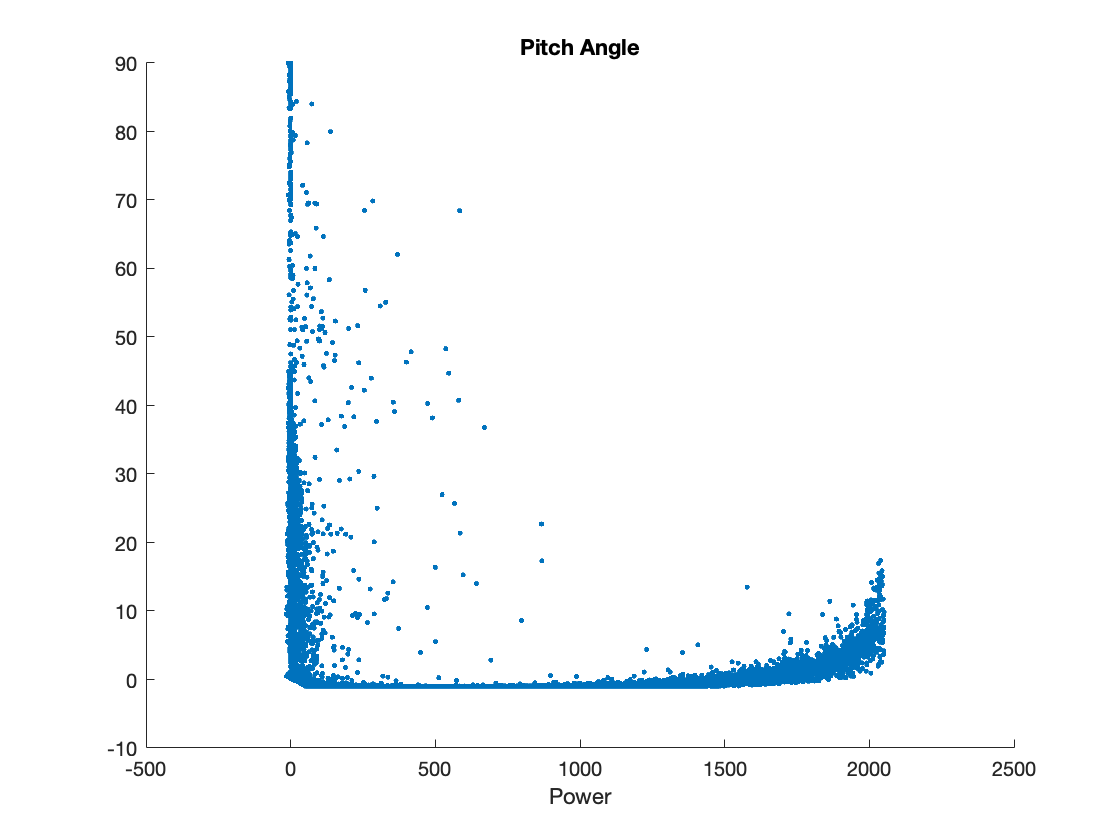

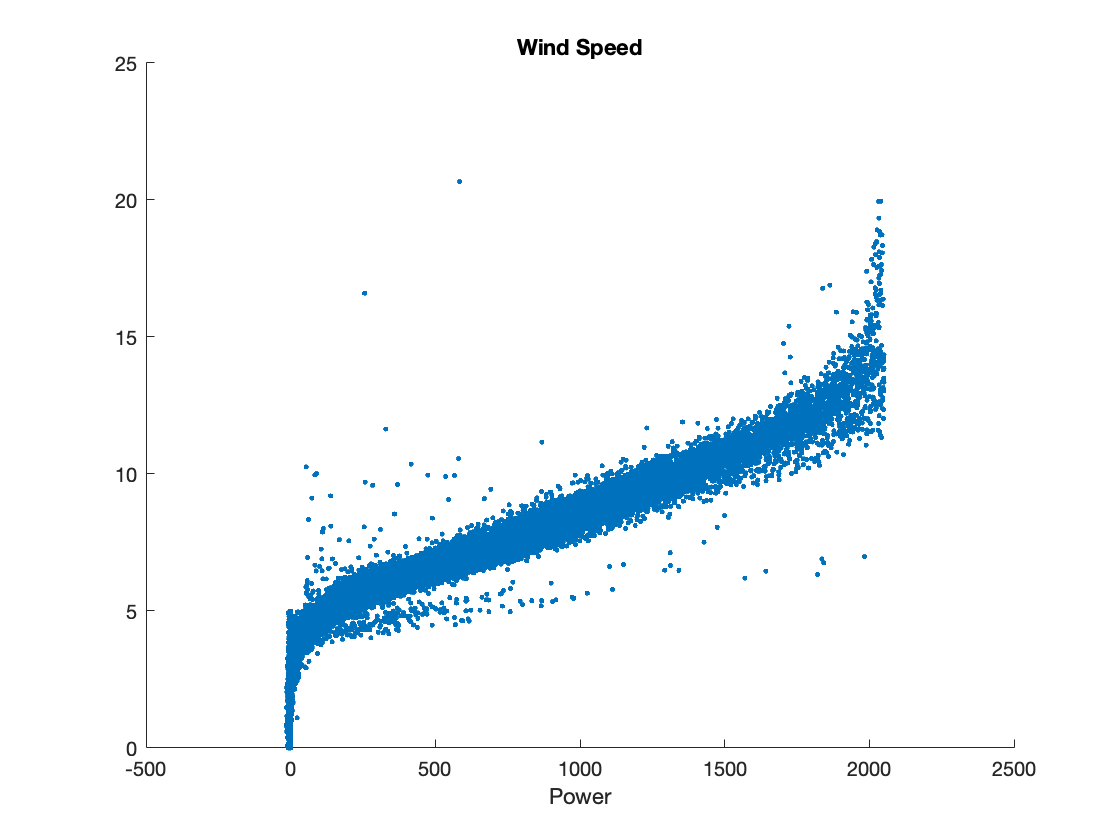

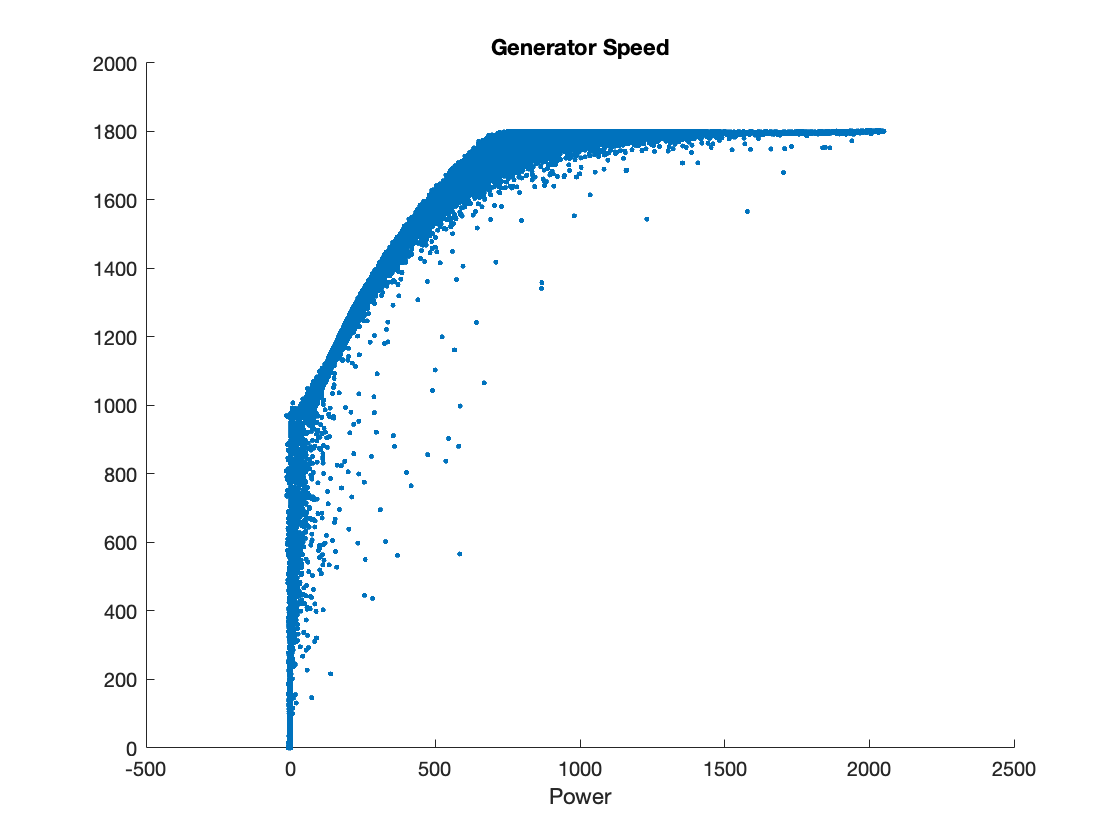

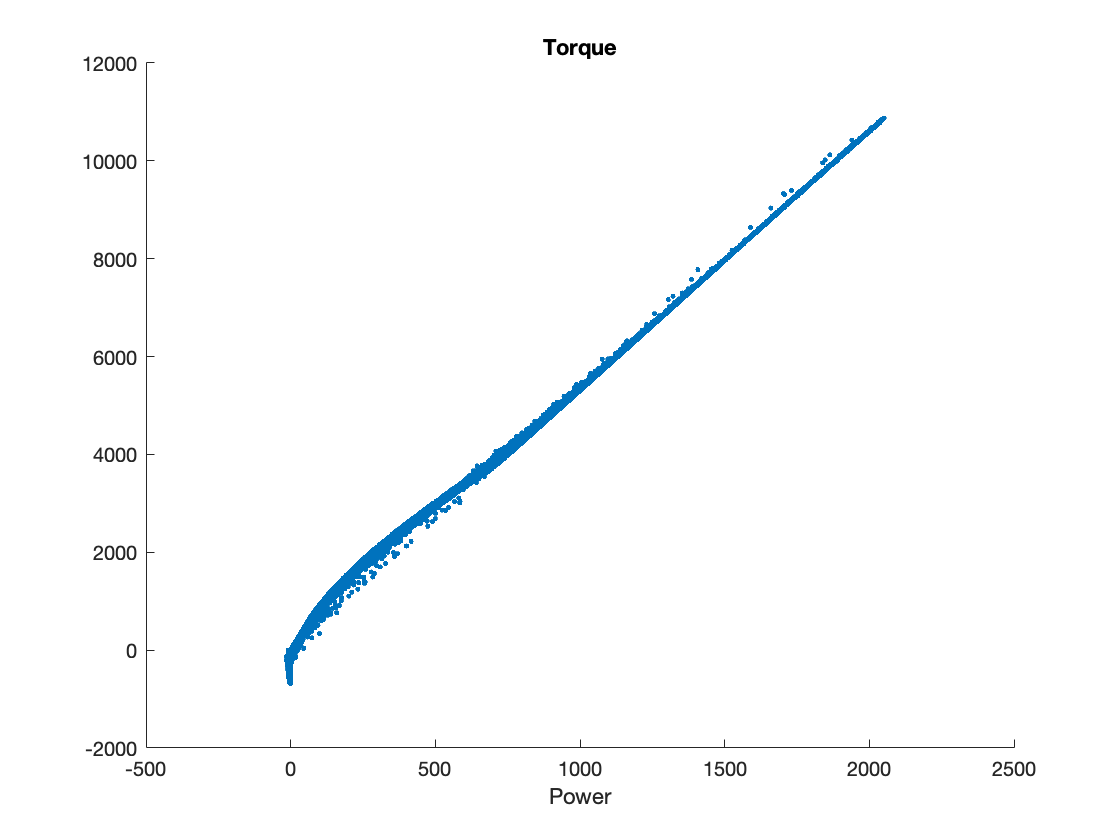

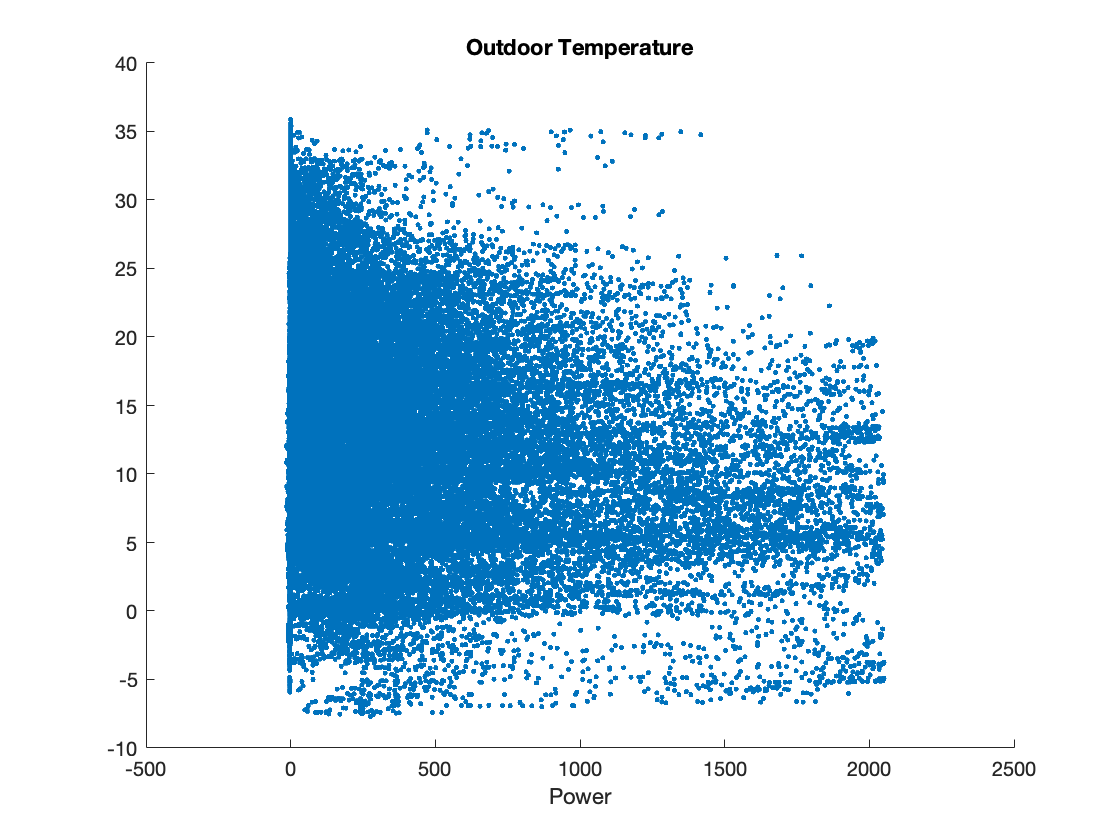


for i = 1:k
    figure(i)
    scatter(data.P_avg, data.(variables_named(i)), ".")
    title(variables_named(i))
    xlabel("Power")
end

## Product Moment Correlation Coefficient

N = length(data.P_avg)

N = 49353


% Calculate standard deviation for x (Power)
y_mean = ones(N, 1) * mean(data.P_avg);
s_y = sqrt(sum((data.P_avg - y_mean).^2) / (N - 1));  % Could also be calculated with std function
p_xy = zeros(k, 1);

% Iterate over all variables
for i = 1:k
    % Calculate standard deviation for y
    y_mean = ones(N, 1) * mean(data.(variables_named(i)));
    s_y = sqrt(sum((data.(variables_named(i)) - y_mean).^2) / (N - 1))

    % Calculate PMCC, could also use corrcoef
    t_x = (data.P_avg - y_mean) / s_y;
    t_y = (data.(variables_named(i)) - y_mean) / s_y;
    
    p_xy(i) =  sum(t_x .* t_y) / (N - 1);
end

s_y = 20.1983

s_y = 2.5550

s_y = 562.1054

s_y = 2.3807e+03

s_y = 7.9845

## Linear Regression

% Standardise model output
y_mean = ones(N, 1) * mean(data.P_avg);
s_y = sqrt(sum((data.P_avg - y_mean).^2) / (N - 1));
Y = (data.P_avg - y_mean) ./ s_y;
X = zeros(N, k);

% Iterate over all variables to create required matrix
for i = 1:k
    % Calculate standard deviation for y
    x_mean = ones(N, 1) * mean(data.(variables_named(i)));
    s_x = sqrt(sum((data.(variables_named(i)) - x_mean).^2) / (N - 1));
    
    % Standardise model inputs
    X(:, i) = (data.(variables_named(i)) - y_mean) ./ s_x;
end

% Calculate b values
% This does not give the correct values, unsure where I went wrong...
b = (X.' * X)^-1 * X.' * Y

b =     0.0266
   -0.0022
   -0.0741
    1.0684
    0.0122


% Calculate R2
SS_tot = sum((data.P_avg - y_mean).^2)

SS_tot = 1.0101e+10

SS_res = sum((data.P_avg - data{:, variables_named} * b).^2)

SS_res = 3.8373e+11

R2 = 1 - SS_res / SS_tot

R2 = -36.9876


% Calculate using built-in MATLAB function
[b, ~, ~, ~, stats] = regress(data.P_avg, data{:, variables_named})

b =     0.5935
   -6.9165
   -0.0486
    0.2077
    0.7674


stats = 	1.0e+06 *

    0.0000    3.1781         0    0.0008


R2 = stats(1)

R2 = 0.9961

% Checking the model with 10 random points, to ensure model is in the correct ball park

% Y = bX
X = randi(N, 10, 1);
Y_actual = data.P_avg(X)

Y_actual =          0
  541.0800
  438.7700
   78.6600
  141.2100
  188.4900
  154.8500
   28.4100
         0
  200.4800


Y_model = data{X, variables_named} * b

Y_model =   -89.3943
  534.1630
  450.6267
   87.9305
  170.2185
  216.3125
  185.2014
    8.8361
  -16.6671
  227.0837


## Variance Based Sensitivity Analysis

% Calculate linear regression b with all data mapped between [0 1]
b = regress(rescale(data.P_avg), rescale(data{:, variables_named}))

b =     3.3054
   -7.9832
   -0.3255
    1.1402
    3.9114



% Create sobol quasirandom number matrices
sob = sobolset(2*k);
A = sob(2:N+1, 1:k);
B = sob(2:N+1, k+1:end);

A_B = zeros(N, k, k);
B_A = zeros(N, k, k);

% Create A_B, where A_B(:, :, i) contains the ith column of matrix B, and
% all other columns from A. Likewise for B_A.
for i = 1:k
    A_B(:, :, i) = [A(:, 1:i-1), B(:, i), A(:, i+1:end)];
    % B_A(:, :, i) = [B(:, 1:i-1), A(:, i), B(:, i+1:end)];
end

A_eval = zeros(N, 1);
B_eval = zeros(N, 1);
A_B_eval = zeros(N, k);

% Evaluate the model for all inputs in A, B, and A_B
parfor i = 1:N
    A_eval(i) = A(i, :) * b;
    B_eval(i) = B(i, :) * b;
    
    for j = 1:k
        A_B_eval(i, j) = A_B(i, :, j) * b;
    end
end

% Calculate the expected reduction and variance in the output, Y
V_X = zeros(5, 1);
E_X = zeros(5, 1);
for i = 1:k
    V_X(i) = mean(B_eval .* (A_B_eval(:, i) - A_eval));
    E_X(i) = 1 / 2 * mean((A_eval - A_B_eval(:, i)).^2);
end

% Not sure what input data is used to calculate Y maybe I can use the sobol
% random numbers - e.g. I can use A_eval?
Y = A_eval;
V = var(Y)

V = 7.6138


S = V_X / V

S =     0.1196
    0.6976
    0.0012
    0.0142
    0.1675


S_T = E_X / V

S_T =     0.1196
    0.6975
    0.0012
    0.0142
    0.1674
